This is an example for how one can prescibe calving in Úa

Note that Úa does not have any inbuild calving laws. It is left to the user to decide if and when some areas are lost due to calving.

The loss of ice due to calving can be described in two different ways: Either by deactivating all elements within a give region, or by manually reducing ice thickness to some minimum value.

Note that if you use the local mesh refinement option:

    CtrlVar.MeshRefinementMethod='explicit:local:newest vertex bisection';

you can de-activate and later re-activate all elements within a given area.  

The possibility of de-activating and re-activating elements gives all kinds of nice options and makes everyone very very happy and content and this is obviously much much better than any level-set options. 

However, remember that you are working in an Eulerian frame and that you are not specifying the calving rate but the position of the calving front. In effect, the problem of figuring out how calving rate affects the calving front position is left to the user. 

To manually deactivate elements, set:

    CtrlVar.ManuallyDeactivateElements=1 ;

in Ua2D_InitialUserInput.m

You then specify which elements to deactivate using the user m-file: 

    DefineElementsToDeactivate.m

If you want to manually modify ice thickness during a transient run then you must set:

    CtrlVar.GeometricalVarsDefinedEachTransienRunStepByDefineGeometry="sb";

in Ua2D_InitialUserInput.m 

You then modify the thickness accordingly in DefineGeometry.m 


 ===== The fields of CtrlVar given as input to Ua replace corresponding fields of CtrlVar defined in Ua2D_InitialUserInput.m 
 Note: CtrlVar.AdaptMeshInterval no longer used. Use CtrlVar.AdaptMeshRunStepInterval instead.
 setting CtrlVar.AdaptMeshRunStepInterval=CtrlVar.AdaptMeshInterval 

 
 **************************     Úa version: 11 November 2019 (alpha)  ********************** 
    Run starts at 13-Nov-2019 13:21:01  
    Experiment: UaDefaultRun  
    Time-independent model run.  
    Running on: C17777347
 ***************************************************************************** 
 
 Creating an input file for gmsh : GmshFile.geo 
Calling gmsh with GmshFile.geo as a geo input file, and creating GmshFile.msh output file 
The gmsh call is:  C:\cygwin64\home\pnjc6\Ua\gmsh-4.3.0-Windows64\gmsh.exe GmshFile.geo -2 -format msh2 -v 1  
Loading GmshFile.msh 
 Reading GmshFile.msh.  
Mesh Type : 2.2 0 8 Reading nodes done.  Reading elements done.
Number of integration points: nip=6 


 =========================================> Current run step: 1 <==================================


 ==> Time independent step. Current run step: 1 
 Starting SSTREAM diagnostic step. 
NR-STREAM(uv):  1/0  g=1              , r/r0=0.479865       ,  r0=1              , r=0.479865       , du=6.129086e+14   , dl=Inf            , Assembly=0.065598 sec. Solution=0.022859 sec.
 NR-STREAM(uv):  2/1  g=1              , r/r0=0.5471584      ,  r0=0.479865       , r=0.2625622      , du=147.3937       , dl=2.774476       , Assembly=0.084804 sec. Solution=0.031882 sec.
 NR-STREAM(uv):  3/10 g=22.84381       , r/r0=0.1506612      ,  r0=0.2625622      , r=0.03955793     , du=700.8649       , dl=0.490419       , Assembly=0.104582 sec. Solution=0.040761 sec.
 NR-STREAM(uv):  4/0  g=1              , r/r0=0.1377084      ,  r0=0.03955793     , r=0.00544746     , du=1.000585       , dl=0.4220082      , Assembly=0.123627 sec. Solution=0.049652 sec.
 NR-STREAM(uv):  5/0  g=1              , r/r0=0.2594393      ,  r0=0.00544746     , r=0.001413285    , du=0.2198096      , dl=0.0120339      , Assembly=0.143059

Exiting run-step loop because total number of steps reached. 
 Calling UaOutputs. UaOutputsInfostring=Last call , UaOutputsCounter=3 
 

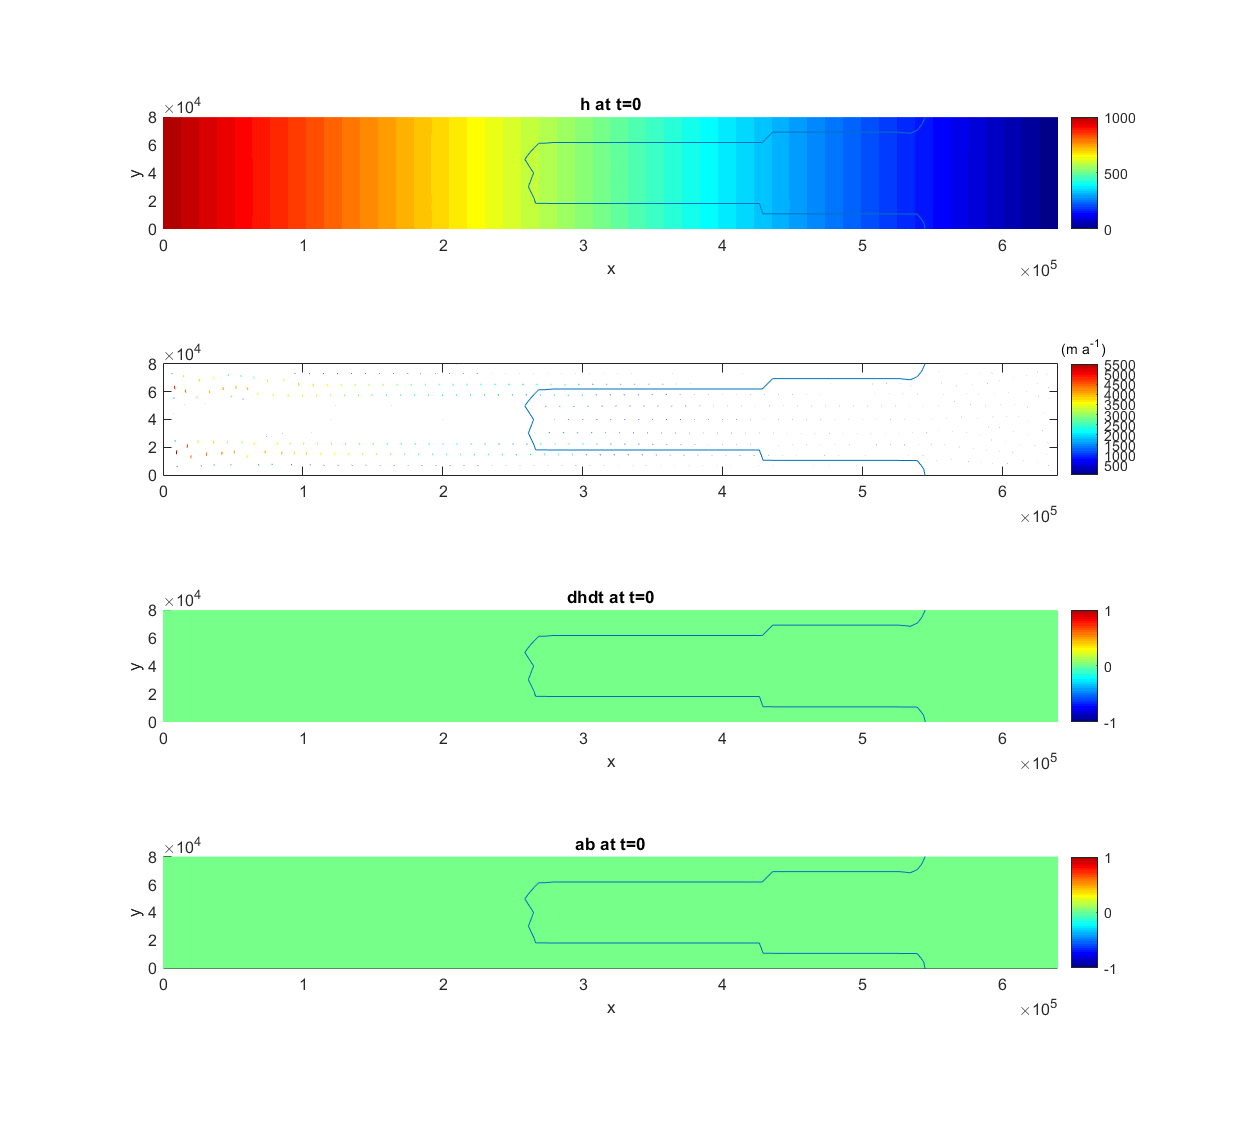

 
 ################## UaDefaultRun 13-Nov-2019 13:21:09 ################### 
 Writing restart file Ua2D_Restartfile.mat  at t=0 
  Writing restart file was successful. 
 Wall-clock time : 00:00:21 (hh:mm:ss) 
 Run finishes at 13-Nov-2019 13:21:09 
 ================           Allt gott þá endirinn er allra bestur!    ======================
 



CtrlVar=Ua2D_DefaultParameters();


CtrlVar.doplots=false ; % this switches internal Ua plots on or off, any plotting done in UaOutputs unaffected
CtrlVar.MeshGenerator="gmsh";

UserVar.RunType="-ManuallyDeactivateElements-";

UserVar=Ua(UserVar,CtrlVar)  ;